## Example 1. Calculating FRF with known track parameters

If we know the values of the parameters for railpad and ballast, e.g. [[1]](https://www.sciencedirect.com/science/article/pii/S0888327020308177),

Railpad    Stiffness1300 MN/m (kp)

                Damping 67.5 kNs/m (cp)

Ballast    Stiffness  90 MN/m (kb)

                Damping 64 kNs/m (cb)

we can calulate and plot the FRF using **black_box_model_optimization**

clear
clc
kp = 1.3e9;
cp = 6.75e4;
kb = 9e7;
cb = 6.4e4;
[H1, fxx] = black_box_model(kp,cp,kb,cb);

Starting Newmark intergration. Time: 17-May-2021 01:20:18
Time step: 1000finished. Time2.4076
Time step: 2000finished. Time4.7979


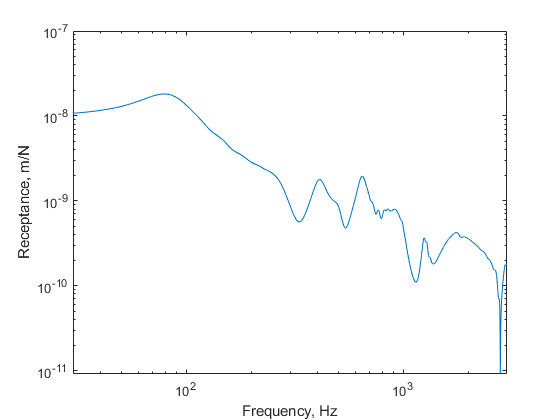

figure;
loglog(fxx,abs(H1))
xlim([30 3000])
xlabel('Frequency, Hz')
ylabel('Receptance, m/N')

writematrix([fxx,abs(H1)],'target_frf_numerical_example.csv') % save results to a .csv file to be used as a target FRF for optimization

## Example 2. Optimization of track parameters based on given FRF (numerical example)

We use the FRF calulated in Example 1 as a target FRF to solve an optimization problem.

- Define the lower and upper bound for kp, cp, kb, cb (see Table 3 in [[1]](https://www.sciencedirect.com/science/article/pii/S0888327020308177))

ub = [1.5e9;7e4;2.8e8;2.8e5]; % upper bound
lb = [1e8;1e4;6e7;4e4];       % lower bound
target_frf = readmatrix("target_frf_numerical_example.csv");

- Define frequency range of interest. Here we use 30 Hz ~ 3000 Hz.

frq_range = find(target_frf(:,1)>30 & target_frf(:,1)<3000);

- Define objective function. 

objFunction = @(para)rms((log(abs(black_box_model_optimization(para,frq_range)))-log(abs(target_frf(frq_range,2))))./log(abs(target_frf(frq_range,2))));

options_pso = optimoptions('particleswarm','FunctionTolerance',1e-4,'MaxTime',600,'Display','iter');
para_optimized = particleswarm(objFunction,...
    4,lb,ub,options_pso);